Homework 5 AE2201

by: Hafizh Renanto Akhmad

References:

- Jaan

## Nomor 1

% Define the matrices
A = [
     4, -2,  2;
    -2,  2, -4;
     2, -4, 11
]

A =      4    -2     2
    -2     2    -4
     2    -4    11


b = [
    2;
    5;
    4
]

b =      2
     5
     4


n = length(A);

### Gauss Elimination

% Initialize augmented matrix
Ab = [A b];

% Forward elminiation
i = 1;
unsolvable = false;

while ((i < n) && ~unsolvable)
    pembagi = Ab(i, i);

    if (pembagi == 0)
        % Exchange row if pivot = 0
        dapet_pivot = false;
        pivot = i + 1;

        while (pivot <= n)
            nilai_pivot = Ab(pivot, i);

            if (nilai_pivot ~= 0)
                dapet_pivot = true;
                break
            else
                pivot = pivot + 1;
            end
        end

        if dapet_pivot
            disp("Switch Row")
            Ab = switch_row(Ab, i, pivot);
        else
            unsolvable = true;
        end
    else
        pengali = zeros(n, 1);
    
        for k = (i+1):n
            pengali(k) = Ab(k, i);
        end
    
        for j = i:(n+1)
            for k = (i+1):n
                Ab(k, j) = Ab(k, j) - Ab(i, j) * pengali(k) / pembagi;
            end
        end
    
        i = i + 1;
    end
end

% Tampilkan hasil matrix augmented
Ab

Ab =      4    -2     2     2
     0     1    -3     6
     0     0     1    21


if unsolvable || Ab(n, n) == 0
    disp("Unsolvable")
else
    % Back Substitution
    x = Ab(:, n+1);
    
    x(n) = x(n) / Ab(n, n);
    
    for i = (n-1):-1:1
        pengurang = 0;
    
        for j = n:-1:(i+1)
            pengurang = pengurang + Ab(i, j) * x(j);
        end
        
        x(i) = (x(i) - pengurang) / Ab(i, i);
    end
    
    % Tampilkan x
    x
end

x =    24.5000
   69.0000
   21.0000


### Cholesky

% Get the lower-triangular matrix
L = choleski(A)

L =      2     0     0
    -1     1     0
     1    -3     1


% Define the upper triangular matrix
U = transpose(L)

U =      2    -1     1
     0     1    -3
     0     0     1



% Substitution for y
y = b(:);

y(1) = y(1) / L(1, 1);

for i = 2:n
    pengurang = 0;

    for j = 1:(i-1)
        pengurang = pengurang + L(i, j) * y(j);
    end

    y(i) = (y(i) - pengurang) / L(i, i);
end

% Tampilkan y
y

y =      1
     6
    21


% Back Substitution for x
x = y(:);

x(n) = x(n) / U(n, n);

for i = (n-1):-1:1
    pengurang = 0;

    for j = n:-1:(i+1)
        pengurang = pengurang + U(i, j) * x(j);
    end
    
    x(i) = (x(i) - pengurang) / U(i, i);
end

% Tampilkan x
x

x =    24.5000
   69.0000
   21.0000


## Nomor 2

clf, clear

% Variable for the problem
s = 0.8;
c = 0.6;

% Define the matrices
A = [
    c,  1,   0, 0, 0;
    0,  s,   0, 0, 1;
    0,  0, 2*s, 0, 0;
    0, -c,   c, 1, 0;
    0,  s,   s, 0, 0
]

A =     0.6000    1.0000         0         0         0
         0    0.8000         0         0    1.0000
         0         0    1.6000         0         0
         0   -0.6000    0.6000    1.0000         0
         0    0.8000    0.8000         0         0


b = [
    0;
    0;
    1;
    0;
    0
]

b =      0
     0
     1
     0
     0


n = length(A);

% First, check if the matrix is diagonally dominant or not
is_diagonal = is_diagonal_dominant(A);
fprintf("Checking Diagonally Dominance: %g\n", is_diagonal)

Checking Diagonally Dominance: 0


A

A =     0.6000    1.0000         0         0         0
         0    0.8000         0         0    1.0000
         0         0    1.6000         0         0
         0   -0.6000    0.6000    1.0000         0
         0    0.8000    0.8000         0         0


b

b =      0
     0
     1
     0
     0


% As we can see, the matrix is not diagonally dominant. We can see that the
% value of diagonal element in 5th row is zero. Let's exchange it with row
% 2. Also, we can see that at row 1, the diagonal element is smaller. So
% let's do an ERO by substracting with the value of row 2 from row 1.
A_changed = A(:,:);
A_changed = switch_row(A_changed, 2, 5);
A_changed = ero(A_changed, 1, 2, -1)

A_changed =     0.6000    0.2000   -0.8000         0         0
         0    0.8000    0.8000         0         0
         0         0    1.6000         0         0
         0   -0.6000    0.6000    1.0000         0
         0    0.8000         0         0    1.0000


% Check again
is_diagonal_second = is_diagonal_dominant(A_changed);
fprintf("Checking Diagonally Dominance After Changing Manually: %g\n", is_diagonal_second)

Checking Diagonally Dominance After Changing Manually: 0


% Now, it's diagonally dominant, thus we may safely do Gaus-Seidel
% iteration. Apply the same to b
A = A_changed(:,:);
b = switch_row(b, 2, 5);
b = ero(b, 1, 2, -1);

% Initialize P as initial guess and the error array
P = ones(n, 1);
P_simpan = ones(n, 1);
P_error = ones(n, 1);

% Declare iteration limit and stop error
iter = 0;
stop_iter = 100;
stop_error = 0.01;

finish = false;

while(~finish)
    % Do the iterative scheme
    for i = 1:n
        sum_to_AP = 0;

        for j = 1:n
            if (i ~= j)
                sum_to_AP = sum_to_AP + A(i, j) * P(j);
            end
        end

        P_simpan(i) = (1 / A(i, i)) * (b(i) - sum_to_AP);
    end

    % Increment iteration
    iter = iter + 1;

    % Store approximate error
    for i = 1:n
        P_error(i) = (P_simpan(i) - P(i)) / P_simpan(i);
    end

    % Update P
    P = P_simpan;

    if (iter >= stop_iter || max(abs(P_error)) < stop_error)
        finish = true;
    end
end

% Show the result
P

P =     1.0417
   -0.6250
    0.6250
   -0.7500
    0.5000


P_error

P_error =      0
     0
     0
     0
     0


## Nomor 3

clf, clear, clc
% Define the matrices
A = [
     6, -4,  1,  0;
    -4,  6, -4,  1;
     1, -4,  6, -4;
     0,  1, -4,  7
]

A =      6    -4     1     0
    -4     6    -4     1
     1    -4     6    -4
     0     1    -4     7


B = [
     1, -2,  3, -1;
    -2,  6, -2,  3;
     3, -2,  6, -2;
    -1,  3, -2,  9
]

B =      1    -2     3    -1
    -2     6    -2     3
     3    -2     6    -2
    -1     3    -2     9


n = length(B);

% Show L
L = choleski(B)

L =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -2.0000 + 0.0000i   1.4142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   3.0000 + 0.0000i   2.8284 + 0.0000i   0.0000 + 3.3166i   0.0000 + 0.0000i
  -1.0000 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.3015i   2.7552 + 0.0000i


L * L'

ans =     1.0000   -2.0000    3.0000   -1.0000
   -2.0000    6.0000   -2.0000    3.0000
    3.0000   -2.0000   28.0000   -0.0000
   -1.0000    3.0000   -0.0000    9.1818


% Show inverse L
inverse_L = L^-1

inverse_L =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   1.4142 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 2.1106i   0.0000 + 0.6030i   0.0000 - 0.3015i   0.0000 + 0.0000i
   0.2310 + 0.0000i  -0.1155 + 0.0000i  -0.0330 + 0.0000i   0.3630 + 0.0000i


% Show inverse L transpose
inverse_L_transpose = transpose(L^-1)

inverse_L_transpose =    1.0000 + 0.0000i   1.4142 + 0.0000i   0.0000 + 2.1106i   0.2310 + 0.0000i
   0.0000 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.6030i  -0.1155 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.3015i  -0.0330 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3630 + 0.0000i


% Show H
H = (L^-1) * A * transpose(L^-1)

H =    6.0000 + 0.0000i   5.6569 + 0.0000i   0.0000 + 9.9499i   1.8148 + 0.0000i
   5.6569 + 0.0000i   7.0000 + 0.0000i   0.0000 +11.5128i   1.7732 + 0.0000i
   0.0000 + 9.9499i   0.0000 +11.5128i -19.4545 + 0.0000i   0.0000 + 3.4422i
   1.8148 + 0.0000i   1.7732 + 0.0000i   0.0000 + 3.4422i   1.5084 + 0.0000i


## Nomor 4

clf, clear, clc
% Define the matrices
A = [
      5,-4, 1, 0, 0, 0, 0, 0;
     -4, 6,-4, 1, 0, 0, 0, 0;
      1,-4, 6,-4, 1, 0, 0, 0;
      0, 1,-4, 6,-4, 1, 0, 0;
      0, 0, 1,-4, 6,-4, 1, 0;
      0, 0, 0, 1,-4, 6,-4, 1;
      0, 0, 0, 0, 1,-4, 6,-4;
      0, 0, 0, 0, 0, 1,-4, 7;
]

A =      5    -4     1     0     0     0     0     0
    -4     6    -4     1     0     0     0     0
     1    -4     6    -4     1     0     0     0
     0     1    -4     6    -4     1     0     0
     0     0     1    -4     6    -4     1     0
     0     0     0     1    -4     6    -4     1
     0     0     0     0     1    -4     6    -4
     0     0     0     0     0     1    -4     7


B = [
      2,-1, 0, 0, 0, 0, 0, 0;
     -1, 2,-1, 0, 0, 0, 0, 0;
      0,-1, 2,-1, 0, 0, 0, 0;
      0, 0,-1, 2,-1, 0, 0, 0;
      0, 0, 0,-1, 2,-1, 0, 0;
      0, 0, 0, 0,-1, 2,-1, 0;
      0, 0, 0, 0, 0,-1, 2,-1;
      0, 0, 0, 0, 0, 0,-1, 2;
]

B =      2    -1     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0
     0    -1     2    -1     0     0     0     0
     0     0    -1     2    -1     0     0     0
     0     0     0    -1     2    -1     0     0
     0     0     0     0    -1     2    -1     0
     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0    -1     2


% Get the lower-triangular matrix
L = choleski(B)

L =     1.4142         0         0         0         0         0         0         0
   -0.7071    1.2247         0         0         0         0         0         0
         0   -0.8165    1.1547         0         0         0         0         0
         0         0   -0.8660    1.1180         0         0         0         0
         0         0         0   -0.8944    1.0954         0         0         0
         0         0         0         0   -0.9129    1.0801         0         0
         0         0         0         0         0   -0.9258    1.0690         0
         0         0         0         0         0         0   -0.9354    1.0607


n = 8;

% Get the H
H = (L^-1) * A * transpose(L^-1)

H =     2.5000   -0.8660   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.8660    2.1667   -0.9428    0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.9428    2.0833   -0.9682   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.9682    2.0500   -0.9798    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.9798    2.0333   -0.9860         0   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.9860    2.0238   -0.9897    0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.9897    2.0179   -0.9922
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.9922    2.9028


% Solve with Jacobi
[eVals, Z] = jacobi(H)

eVals =     3.7082
    1.2913
    2.6595
    0.6897
    3.9493
    0.2431
    1.9754
    3.2612


Z =     0.3278    0.3551   -0.5120    0.2106    0.1358    0.0804   -0.4685   -0.4643
   -0.4573    0.4956    0.0943    0.4403   -0.2272    0.2095   -0.2838    0.4081
    0.4466    0.1340    0.4210    0.4962    0.3048    0.3535    0.3728   -0.0473
   -0.3042   -0.3730   -0.3424    0.2855   -0.3663    0.4679    0.3179   -0.3398
    0.0735   -0.4212   -0.2031   -0.0940    0.4087    0.5135   -0.3442    0.4668
    0.1775    0.0537    0.4692   -0.4118   -0.4302    0.4674   -0.3361   -0.2436
   -0.3753    0.4593   -0.0991   -0.4614    0.4298    0.3294    0.3264   -0.1604
    0.4623    0.2828   -0.4040   -0.2069   -0.4075    0.1229    0.3492    0.4441


X = transpose(L^-1) * Z;
for i = 1:n % Normalize eigenvectors.
    xMag = sqrt(dot(X(:,i),X(:,i)));
    X(:,i) = X(:,i)/xMag;
end

[eVals,X] = sortEigen(eVals,X); % Sort in ascending order.

% Show all eigenvalues
eVals'

ans =     0.2431    0.6897    1.2913    1.9754    2.6595    3.2612    3.7082    3.9493


% Show all eigenvectors
X

X =     0.2190    0.2374    0.3829   -0.3252   -0.3851   -0.2430    0.2288    0.0445
    0.3946    0.2832    0.3235    0.0718    0.1468    0.4373   -0.2442   -0.2276
    0.4939    0.0779   -0.0493    0.4865    0.0739   -0.0469    0.4815    0.1175
    0.5027   -0.2648   -0.2019    0.1795   -0.5171    0.0143   -0.1386   -0.4240
    0.4285   -0.5364    0.1149   -0.1630   -0.1616    0.5522    0.3416    0.1456
    0.2994   -0.5775    0.5443    0.2153    0.0878   -0.0565    0.2881   -0.5639
    0.1564   -0.3875    0.5839    0.6469   -0.5393    0.3042    0.0459    0.1087
    0.0442   -0.1255    0.2348    0.3589   -0.4823    0.5888    0.6597   -0.6337


% Show used eigenvalues and vectors for plotting

eigenvalues = eVals(1:3)' % Extract 3 smallest

eigenvalues =     0.2431    0.6897    1.2913


eigenvectors = X(:,1:3) % eigenvalues & vectors.

eigenvectors =     0.2190    0.2374    0.3829
    0.3946    0.2832    0.3235
    0.4939    0.0779   -0.0493
    0.5027   -0.2648   -0.2019
    0.4285   -0.5364    0.1149
    0.2994   -0.5775    0.5443
    0.1564   -0.3875    0.5839
    0.0442   -0.1255    0.2348


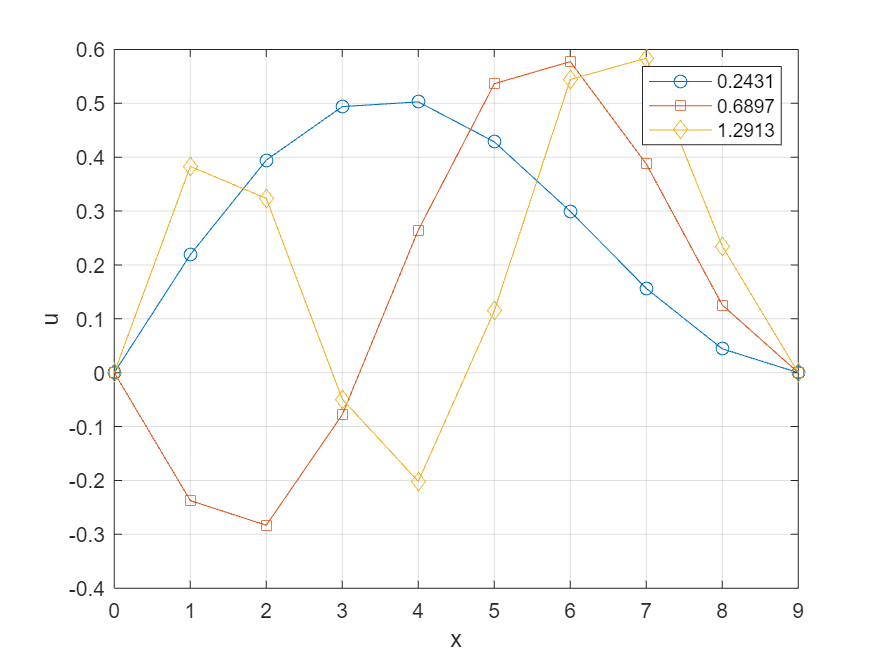

n = length(eigenvectors);

% Plot the 3 lowest eigenvalue
x = 0:9;
x_1 = zeros(1,10);
x_2 = zeros(1,10);
x_3 = zeros(1,10);

for i = 1:8
    x_1(i+1) = X(i, 1);
end

for i = 1:8
    % Use - for similarity with book
    x_2(i+1) = -X(i, 2);
end

for i = 1:8
    x_3(i+1) = X(i, 3);
end

clf
u1 = plot(x, x_1, "Marker","o");
hold on
u2 = plot(x, x_2, "Marker","square");
u3 = plot(x, x_3, "Marker","diamond");
grid on
xlabel('x')
ylabel('u')
ylim([-0.4 0.6])
legend([["0.2431" "0.6897" "1.2913"]])
hold off

function result = is_diagonal_dominant(matrix)

n = length(matrix);

sum = zeros(n, 1);

for i = 1:n
    for j = 1:n
        if (i ~= j)
            sum(i) = sum(i) + matrix(i, j);
        end
    end
end

result = true;

for k = 1:n
    if (abs(matrix(k, k)) < abs(sum(k)))
        result = false;
    end
end

end
function M = switch_row(A, a, b)

% Store the initial row a
N = A(a,:);
M = A(:,:);

% Replace value in row a with value in row b
for i = 1:length(N)
    M(a, i) = M(b, i);
end

% Replace value in row b with store value in row a
for i = 1:length(N)
    M(b, i) = N(i);
end

end

function L = choleski(matrix)

n = length(matrix);

% Initiate lower-triangular matrix
L = zeros(n, n);

% Fill L
for i = 1:n
    for j = 1:(i - 1)
        sum_LL = 0;
    
        for k = 1:(j - 1)
            sum_LL = sum_LL + L(j, k) * L(i, k);
        end
    
        L(i, j) = (matrix(i, j) - sum_LL) / L(j, j);
    end

    sum_L2 = 0;

    for k = 1:(i - 1)
        sum_L2 = sum_L2 + (L(i, k))^2;
    end

    L(i, i) = sqrt(matrix(i,i) - sum_L2);
end

end

function transposed = transpose(matrix)

% Initialize the result
transposed = matrix(:,:);
n = length(transposed);

for i = 1:n
    for j = 1:n
        transposed(i, j) = matrix(j, i);
    end
end

end

function new_matrix = ero(matrix, row_target, row_used, multiplier)

new_matrix = matrix(:,:);

columns = size(matrix, 2);

for i = 1:columns
    new_matrix(row_target, i) = new_matrix(row_target, i) + new_matrix(row_used, i) * multiplier;
end

end

function [eVals, eVecs] = jacobi(A,tol)
% Credit to Jaan (2009)
% Jacobi method for computing eigenvalues and
% eigenvectors of a symmetric matrix A.
% USAGE: [eVals,eVecs] = jacobi(A,tol)
% tol = error tolerance (default is 1.0e-9).
if nargin < 2; tol = 1.0e-9; end
n = size(A,1);
maxRot = 5*(n^2); % Limit number of rotations
P = eye(n); % Initialize rotation matrix
for i = 1:maxRot % Begin Jacobi rotations
    [Amax,k,L] = maxElem(A);
    if Amax < tol
        eVals = diag(A); eVecs = P;
        return
    end
    [A,P] = rotate(A,P,k,L);
end

end

function [Amax,k,L] = maxElem(A)

% Finds Amax = A(k,L) (largest off-diag. elem. of A).
n = size(A,1);
Amax = 0;
for i = 1:n-1
    for j = i+1:n
        if abs(A(i,j)) >= Amax
            Amax = abs(A(i,j));
            k = i; L = j;
        end
    end
end

end

function [A,P] = rotate(A,P,k,L)
% Credit to Jaan (2009)
% Zeros A(k,L) by a Jacobi rotation and updates
% transformation matrix P.
n = size(A,1);
diff = A(L,L) - A(k,k);
if abs(A(k,L)) < abs(diff)*1.0e-36
    t = A(k,L);
else
    phi = diff/(2*A(k,L));
    t = 1/(abs(phi) + sqrt(phi^2 + 1));

    if phi < 0
        t = -t;
    end
end
c = 1/sqrt(t^2 + 1); s = t*c;
tau = s/(1 + c);
temp = A(k,L); A(k,L) = 0;
A(k,k) = A(k,k) - t*temp;
A(L,L) = A(L,L) + t*temp;
for i = 1:k-1 % For i < k
    temp = A(i,k);
    A(i,k) = temp -s*(A(i,L) + tau*temp);
    A(i,L) = A(i,L) + s*(temp - tau*A(i,L));
end
for i = k+1:L-1 % For k < i < L
    temp = A(k,i);
    A(k,i) = temp - s*(A(i,L) + tau*A(k,i));
    A(i,L) = A(i,L) + s*(temp - tau*A(i,L));
end
for i = L+1:n % For i > L
    temp = A(k,i);
    A(k,i) = temp - s*(A(L,i) + tau*temp);
    A(L,i) = A(L,i) + s*(temp - tau*A(L,i));
end
for i = 1:n % Update transformation matrix
    temp = P(i,k);
    P(i,k) = temp - s*(P(i,L) + tau*P(i,k));
    P(i,L) = P(i,L) + s*(temp - tau*P(i,L));
end

end

function [eVals,eVecs] = sortEigen(eVals,eVecs)
% Credit to Jaan (2009)
% Sorts eigenvalues & eigenvectors into ascending order of eigenvalues.
% USAGE: [eVals,eVecs] = sortEigen(eVals,eVecs)
n = length(eVals);
for i = 1:n-1
    index = i; val = eVals(i);
    for j = i+1:n
        if eVals(j) < val
            index = j; val = eVals(j);
        end
    end
    if index ~= i
        eVals = switch_row(eVals,i,index);
        eVecs = switch_col(eVecs,i,index);
    end
end

end

function M = switch_col(A, a, b)

% Store the initial col a
N = A(:,a);
M = A(:,:);

% Replace value in col a with value in col b
for i = 1:length(N)
    M(i, a) = M(i, b);
end

% Replace value in col b with store value in col a
for i = 1:length(N)
    M(i, b) = N(i);
end

end